# Random Processes

## Random Processes

A random process can be thought of a bin that contains multiple signals of infinite length. Every time, we perform a random experiment, we randomly pick one *realization *of the process.

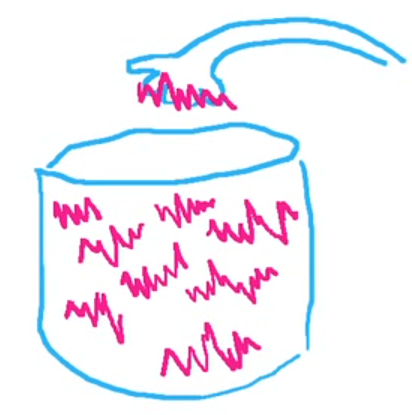 

Why work with random processes? Because we need a mathematical description of the random nature of the process that generated the observed values of a given signal.

We cannot predict the effects of an LTI system on any specific realization of the input process. But we can accurately predict its effect on **the average properties**. In other words, since we cannot have a mathematical model of random signals, we create a statistical model. 

### Stationary Process

A stationary random process is a process which characteristics that do not change over time i.e., for different values of $n$. 

This implies:

a) The mean and the variance of a signal $x\left\lbrack n\right\rbrack$ randomly picked from the stationary process does not depend on time $n$ but is constant:

b) For two signals $x\left\lbrack n\right\rbrack$ and $x\left\lbrack m\right\rbrack$ randomly picked from the stationary process, the autocorrelations and autocovariance only depend on the lag $\ell$ and not time:

   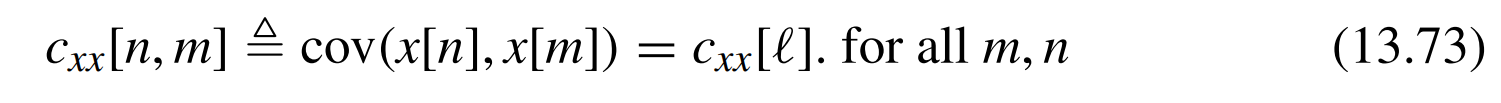

#### Wide-sense Stationary Process

Wide-sense stationary (WSS): A random process that satisfies both a) and b) are called *wide-sense stationary* or *second-order stationary*.

#### Autocorrelation of wide-sense stationary process

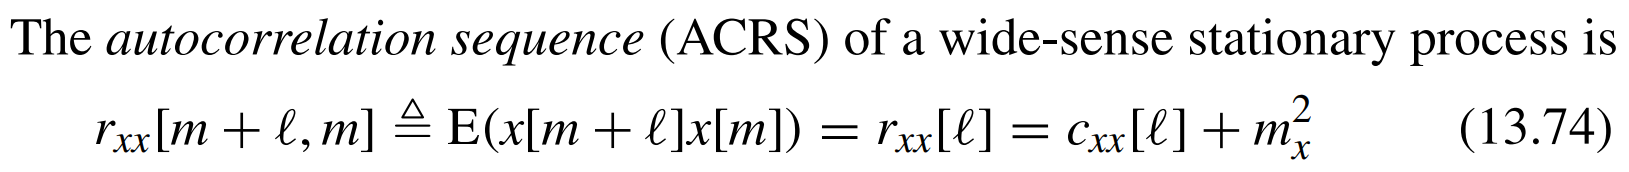

#### Examples of non-stationary signals

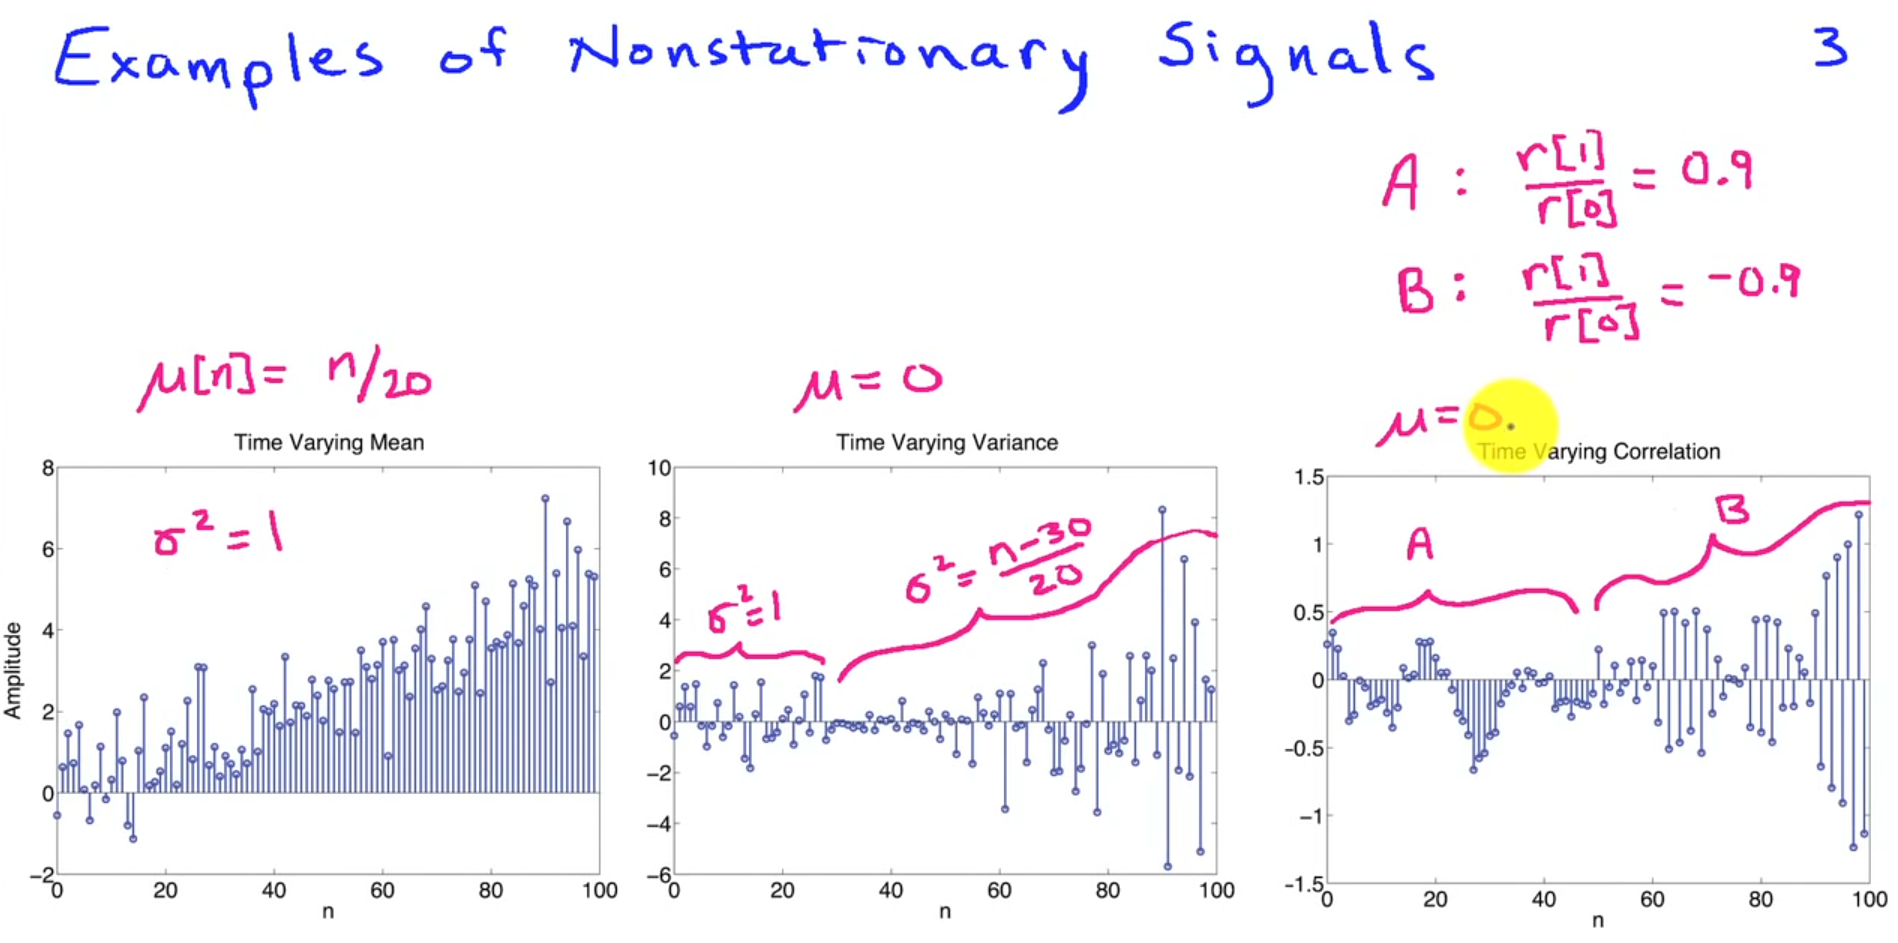

#### Examples of stationary signals

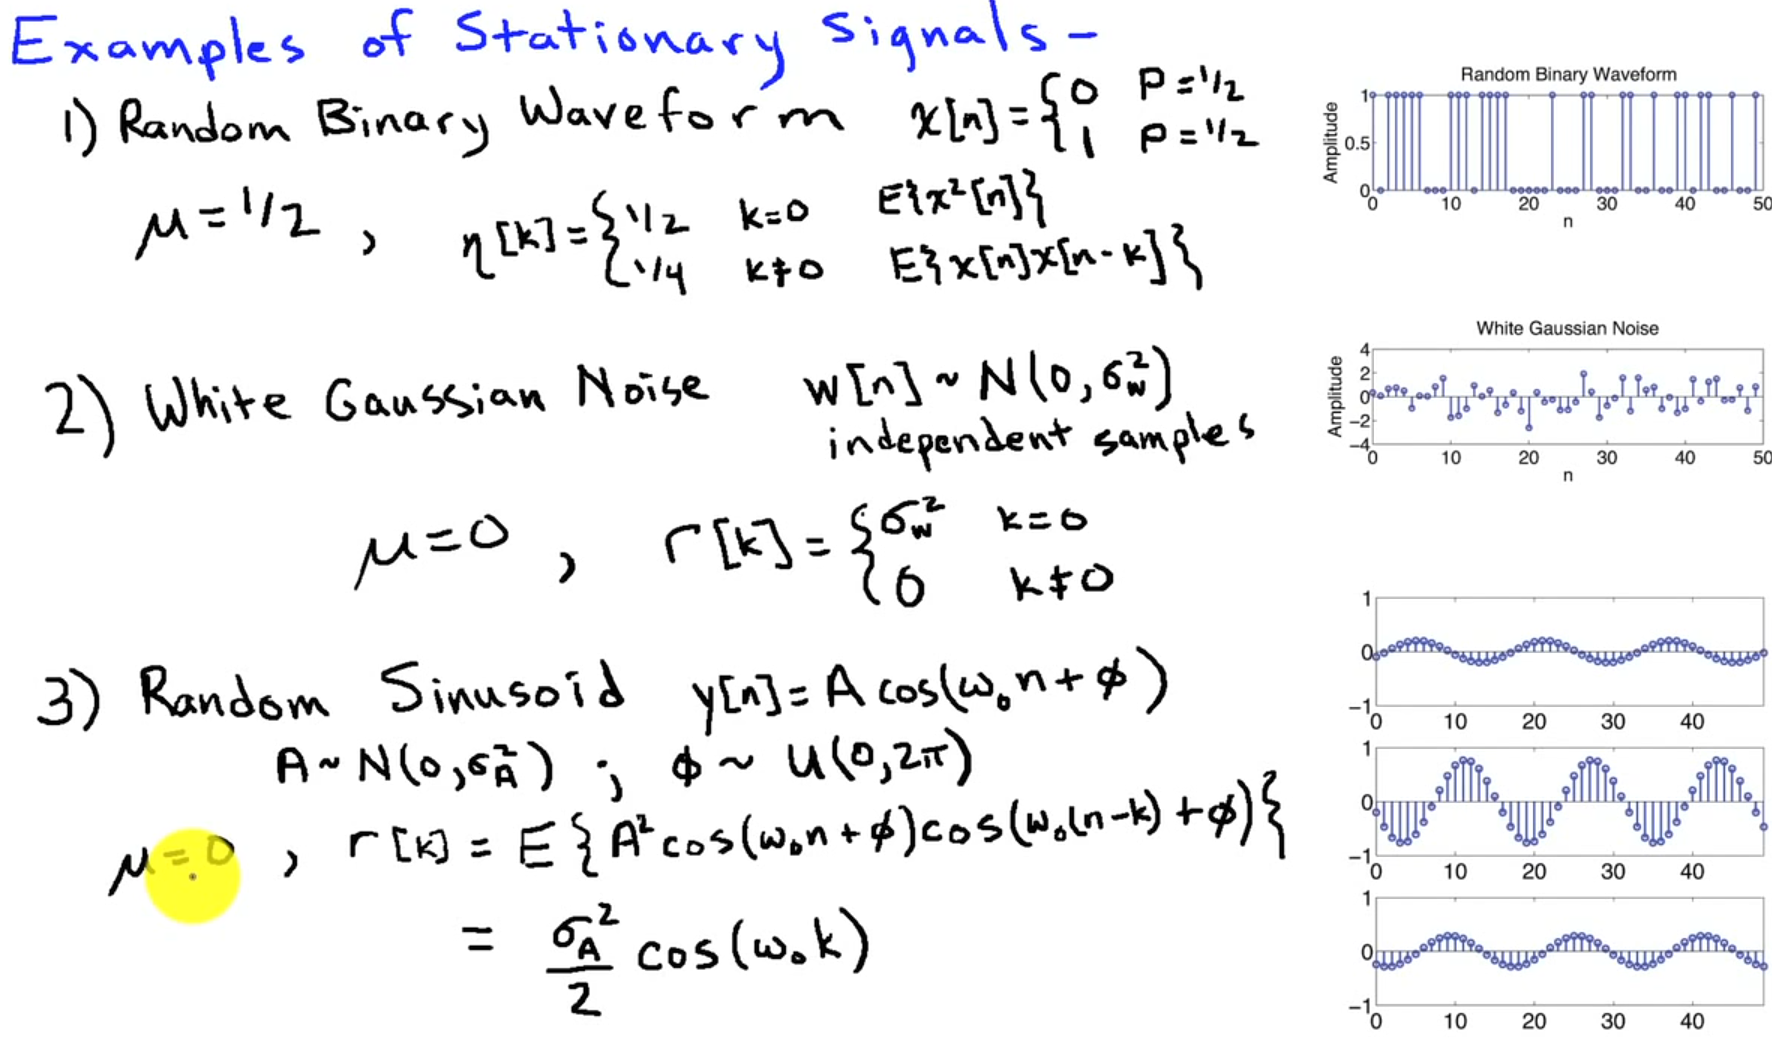

## Problem 13.9: A stationary sinusodial random process

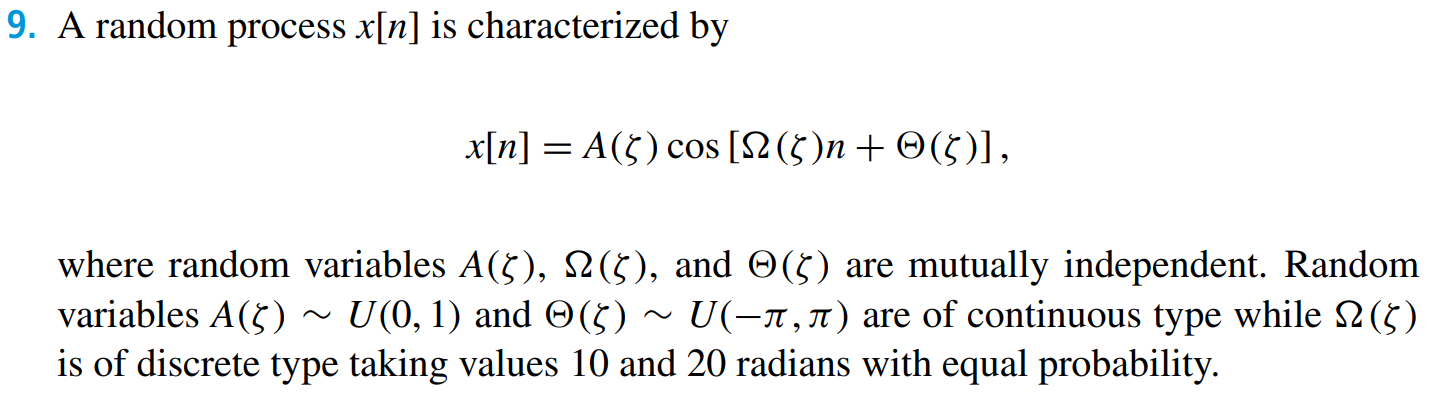

### a) Determine the mean sequence $m_x \left\lbrack n\right\rbrack$

We need to compute:


$$E\left\lbrack x\left\lbrack n\right\rbrack \right\rbrack =E\left\lbrack A\;\mathrm{cos}\left(\Omega n+\Theta \right)\right\rbrack$$


Since the three random variables are independent then we can write:


$$E\left\lbrack x\left\lbrack n\right\rbrack \right\rbrack =E\left\lbrack A\right\rbrack E\left\lbrack \;\cos \left(\Omega n+\Theta \right)\right\rbrack$$


We know that $E\left\lbrack A\right\rbrack =\frac{1}{2}$ since $A\sim U\left(0,1\right)$.

To find the expected value of a function, we need to compute the integral of the function weighted by density of the random quantity $f_{\Theta } \left(\Theta \right)$. Formally, we can write:


$$E\left\lbrack \cos \left(\Omega n+\Theta \right)\right\rbrack =\int_{-\pi }^{\pi } f_{\Theta } \left(\Theta \right)\cdot \cos \left(\Omega n+\Theta \right)\;d\Theta$$


Since $\Theta$ is uniform between $-\pi$ and $\pi$, the density is:


$$f_{\Theta } \left(\Theta \right)=\frac{1}{2\pi }$$


So the expection of the function becomes:


$$E\left\lbrack \cos \left(\Omega n+\Theta \right)\right\rbrack =\int_{-\pi }^{\pi } \frac{1}{2\pi }\cos \left(\Omega n+\Theta \right)\;d\Theta$$


We can bring out the constant outside the integral:


$$E\left\lbrack \cos \left(\Omega n+\Theta \right)\right\rbrack =\frac{1}{2\pi }\int_{-\pi }^{\pi } \cos \left(\Omega n+\Theta \right)\;d\Theta$$


The integral of $\mathrm{cos}\left(n\right)$ is $\mathrm{sin}\left(n\right)$ so we have:


$$E\left\lbrack \cos \left(\Omega n+\Theta \right)\right\rbrack =\frac{1}{2\pi }{\left\lbrack \mathrm{sin}\left(\Omega n+\Theta \right)\right\rbrack }_{-\pi }^{\pi } =\frac{1}{2\pi }\left\lbrack \mathrm{sin}\left(\Omega n+\pi \right)-\mathrm{sin}\left(\Omega n-\pi \right)\right\rbrack$$


Looking up the trigonometric identities:

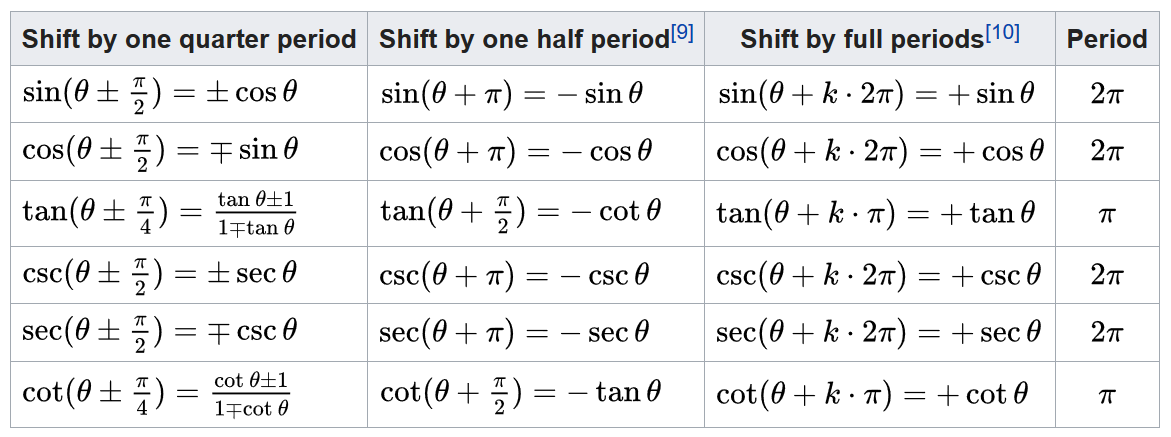

We see that $\mathrm{sin}\left(\Omega n+\pi \right)=-\mathrm{sin}\left(\Omega n\right)$ and $-\mathrm{sin}\left(\Omega n-\pi \right)=\mathrm{sin}\left(\Omega n\right)$. Substituting these identities we get:


$$E\left\lbrack \cos \left(\Omega n+\Theta \right)\right\rbrack =\frac{1}{2\pi }\left\lbrack -\mathrm{sin}\left(\Omega n\right)+\sin \left(\Omega n\right)\right\rbrack =0$$


Therefore: $E\left\lbrack \cos \left(\Omega n+\Theta \right)\right\rbrack =0$

We can visualise why the expected value of $\cos \left(\Omega n+\Theta \right)$ is zero.

Suppose we want to compute $E\left\lbrack \mathrm{cos}\left(\Omega n+\Theta \right)\right\rbrack$ where $\Theta \sim U\left(-\pi ,\pi \right)$. Let us pick one frequency $\omega$ (realise one value of $\Omega$). Then let us pick a lot of realisations of $\Theta$. Now if we plot the function $\mathrm{cos}\left(\omega \;n+\theta \right)$ for different values of $\theta$ then we will see something like this:

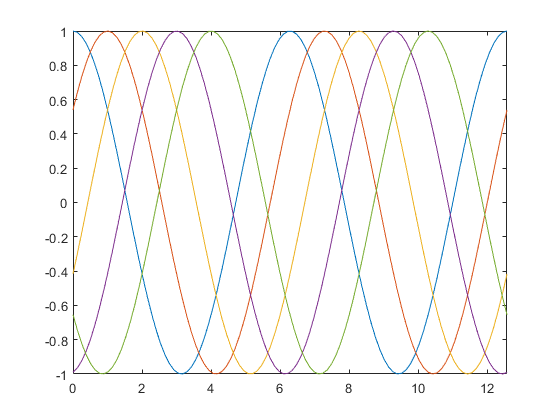

n = linspace(0, 4*pi);
plot(n, cos(n), n, cos(n-1), n, cos(n-2), n, cos(n-3), n, cos(n-4));
xlim([0, 4*pi]);

If we plot hundreds of cosine functions shifted slightly, we get a large blob of points from -1 to 1. For this reason, the quantity $E\left\lbrack \cos \left(\Omega n+\Theta \right)\right\rbrack$ will be zero because the mean value is 0.

In signal processing, we like to add random shifts ala $\Theta \sim U\left(0,2\pi \right)$ to avoid that the expected value or the mean value becomes dependent on time. 

### b) Determine the autocovariance sequence ACVS $c_X \left\lbrack m,n\right\rbrack$

The ACVS provides a measure of the linear dependence between the values of a random process at two different times. In this sense, it determines how quickly the signal amplitude changes from sample to sample (time variation).

To compute the autocovariance sequence, we use the following equation:

 

The formula relates the cross-correlation $r_{\mathrm{xy}} \left\lbrack n,m\right\rbrack$ and cross-covariance $c_{\mathrm{xy}} \left\lbrack n,m\right\rbrack$. It states that the cross-correlation is the cross-covariance added with the product of the means of the two signals.

From a) we know that the expected value (mean) of the given random process is zero. This essentially means that the cross-correlation and the cross-covariance are the same.

This is also clear from the definition of the cross-covariance and cross-correlation.

The cross-covariance for a random process defined as:


$$c_{\mathrm{xy}} \left\lbrack n,m\right\rbrack =E\left\lbrace \left(x\left\lbrack n\right\rbrack -E\left\lbrace x\left\lbrack n\right\rbrack \right\rbrace \right)\left(y\left\lbrack m\right\rbrack -E\left\lbrace y\left\lbrack m\right\rbrack \right\rbrace \right)\right\rbrace$$


The cross-correlation for a random process is defined as:


$$r_{\mathrm{xy}} \left\lbrack n,m\right\rbrack =E\left\lbrace x\left\lbrack n\right\rbrack y\left\lbrack m\right\rbrack \right\rbrace$$


*The term “auto” comes about because the two random variables are taken from the same process.*

Note that when $E\left\lbrace x\left\lbrack n\right\rbrack \right\rbrace =E\left\lbrace y\left\lbrack m\right\rbrack \right\rbrace =0$ then $c_{\mathrm{xy}} \left\lbrack n,m\right\rbrack =r_{\mathrm{xy}} \left\lbrack n,m\right\rbrack$.

syms A
f = A^2;
int(f, A, 0, 1)

$$ans = \frac{1}{3}$$

The result from the solution set:

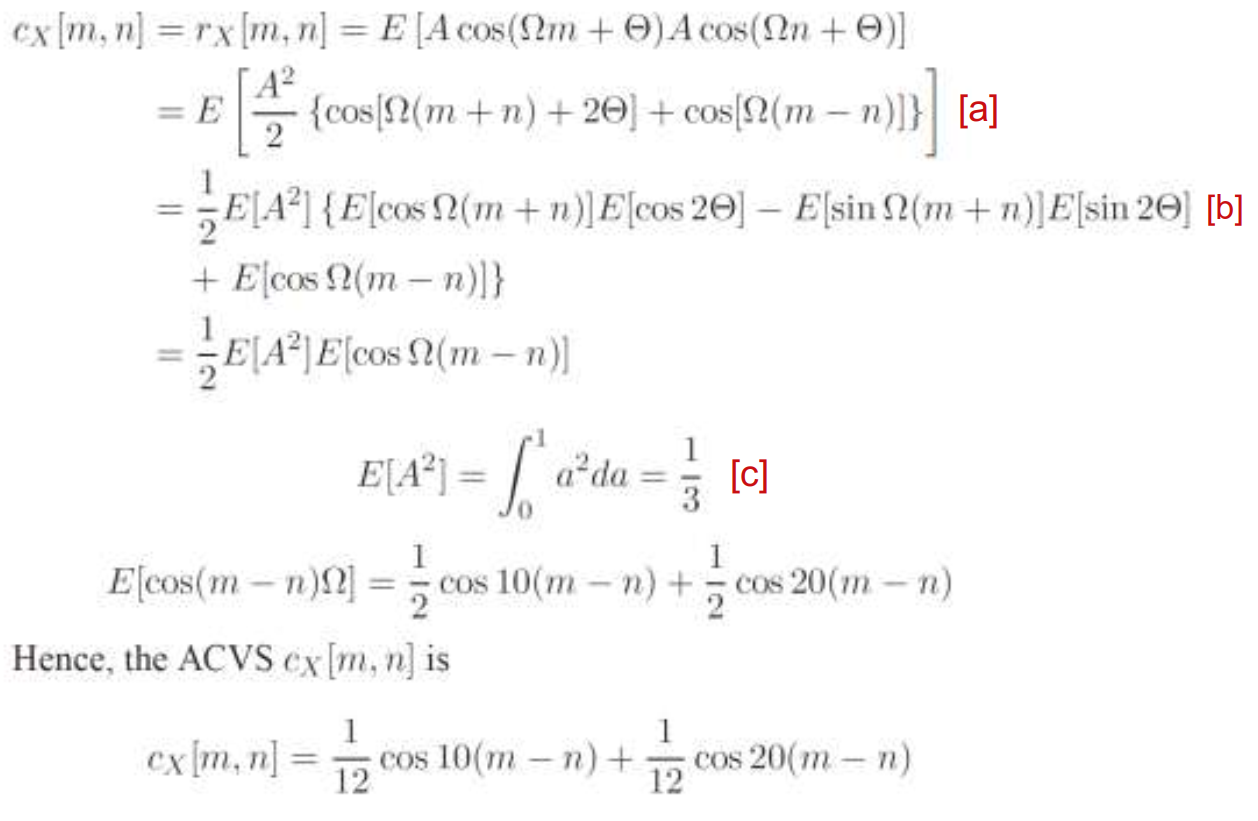

where $\ell =m-n$

Following identities were used in the solution:

[a] $\mathrm{cos}\left(\alpha \right)\mathrm{cos}\left(\beta \right)=\frac{1}{2}\left(\mathrm{cos}\left(\alpha +\beta \right)+\mathrm{cos}\left(\alpha -\beta \right)\right)$

[b] $\mathrm{cos}\left(\alpha +\beta \right)=\mathrm{cos}\left(\alpha \right)\mathrm{cos}\left(\beta \right)-\mathrm{sin}\left(\alpha \right)\mathrm{sin}\left(\beta \right)$

[c] $E\left\lbrack X^n \right\rbrack =\int_{-\infty }^{\infty } x^n \cdot f_X \left(x\right)\;\mathrm{dx}$

### c) Comment on the stationarity of the random process

First, let us defined what the stationarity of a random process is.

A random process is said to be stationary if its characteristics does not change over time. This means that:

i) The mean and the variance of the process is constant:

ii) The auto-correlation and auto-covariance only depend on the lag $\ell$:

If a random process fulfills both requirements, then it is said to be wide-sense stationary. 

In a) we showed the mean of the process is zero.

In b) we showed that the autocovariance only depends on the lag $\ell =m-n$.

Therefore, we can conclude that the random process $x\left\lbrack n\right\rbrack$ is wide-sense stationary.

**Notice this:**

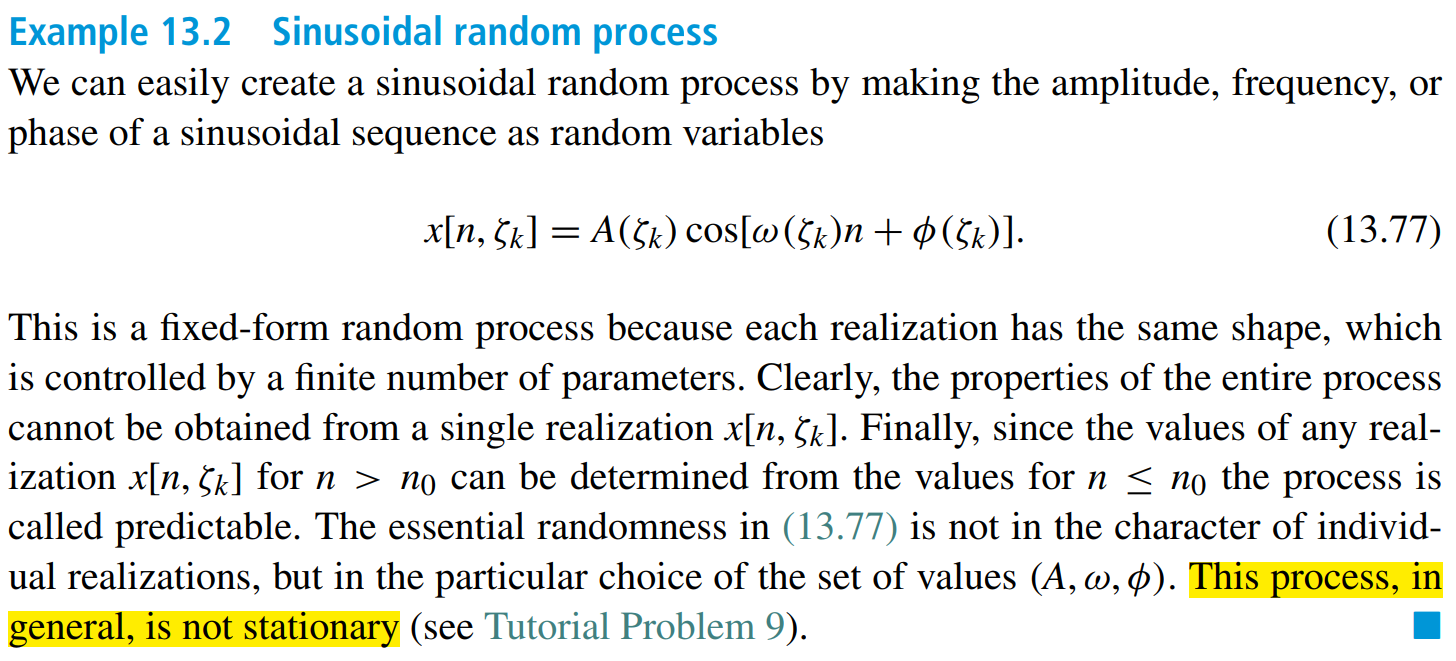

The result of tutorial problem 9 is obtained for one particular way of generating the randomness of the amplitude, phase and frequencies.  You can generate other random processes where the stationarity breaks  down. One good example I often use it to constrain the randomness of the phase. In tutorial problem 9 (and for that matter any other time we  have used sinusoidal signals in the course) we have chosen the phase as  being uniformly distributed between 0 and $2\pi$. If you instead constrain the phase to be, say a uniformly random number between 0 and 0.1, the process is no longer stationary. You can  convince yourself of this result by drawing two figures with many  sinusoids with the same amplitude and frequency, but with either choice  of phase.  

In all the problems, we have looked at in the course, we always use the 0 to $2\pi$ choice and we consider sinusoids as stationary.